Open the dataset

close all; clear; clc

train = readtable("train.csv");

Transported 

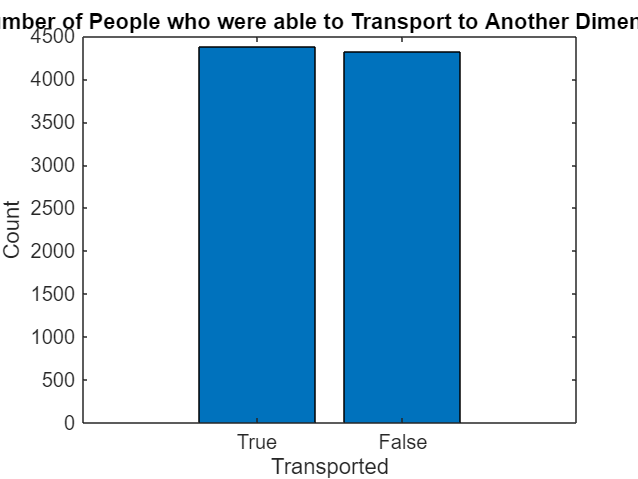

% Count how much transported and not transported
transported = table2array(train(:,"Transported")) == "True";
transported = sum(transported);
untransported = length(table2array(train(:,"Transported"))) - transported;

% Plotting
bar([transported untransported]);
set(gca, 'XTickLabel', {'True','False'});
xlabel("Transported");
ylabel("Count");
title("Number of People who were able to Transport to Another Dimension")

Age distribution and transportation chances

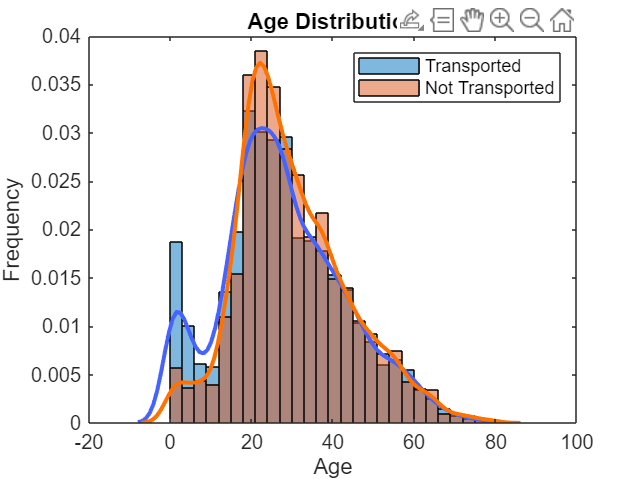

% Initialize the numbers
age = table2array(train(:,"Age"));
transported = table2array(train(:,"Transported"));

% transported stats
transported_idx = transported == "True";;
untransported_idx = transported == "False";;
ageTransported = age(transported_idx);
ageUntransported = age(untransported_idx);

% Plot
histogram(ageTransported,'Normalization', 'pdf', 'FaceAlpha', 0.5);
hold on;
histogram(ageUntransported,'Normalization', 'pdf', 'FaceAlpha', 0.5);
[f1, xf1] = kde(ageTransported);
plot(xf1,f1, 'LineWidth', 2, 'Color', '#4662FF');
[f2, xf2] = kde(ageUntransported);
plot(xf2,f2, 'LineWidth', 2, 'Color', '#FF7200');
legend({'Transported', 'Not Transported'});
hold off;
xlabel('Age');
ylabel('Frequency')
title('Age Distribution');

Expenditures